# **SG_enrichment:**

## **Main steps:**

- **Load desired files.**

- **Parse files into channels.**

- **Detect and mask cells. **

- **Detect and mask stress granules and their local background.**

- **Parse stress granules into cells.**

- **Determine mean and median intensity in stress granules and local background.**

- **Calulate SNR.**

- **Tabulate all information for SNR in a cell and in a replicate. **

clear
clc

% Collect user-selected image files.
[ND2names, ND2pathlist] = getND2Pathlist();
disp(ND2names)

    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_001.nd2'}
    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_002.nd2'}
    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_003.nd2'}
    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_004.nd2'}
    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_005.nd2'}
    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_006.nd2'}
    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_007.nd2'}
    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_008.nd2'}
    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_009.nd2'}
    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_010.nd2'}
    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_011.nd2'}
    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_012.nd2'}
    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_013.nd2'}
    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_014.nd2'}
    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_017.nd2'}
    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_018.nd2'}
    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_020.nd2'}
    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_021.nd2'}
    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_022.nd2'}
    {'210903_GFP-G3BP1_Halo-ACTB-6xSyn_023.nd2'}
    {'210903_GFP-G3B

SGmarkerCh = 1;
probeCh = 2; 
RNAmarkerCh = 3;
show_img = false;
show_withMIP = false;

fprintf('%s%s', 'Starting image import.', newline);

Starting image import.



% Move full path names to processed file.
for p = 1:numel(ND2pathlist) % for every file
    processed{p,1} = ND2pathlist(p);
end

% Open image files.
for f = 1:length(ND2pathlist) % for every file
    
    % Import raw data and save.
    raw = importND2(ND2pathlist{f});
    %processed{f,2} = raw;
    
    % Maximum intensity project the probe channel and save.
    probe_mip = oneChMIP(raw, probeCh);
    %processed{f,3} = probe_mip;
    processed{f,2} = probe_mip;
    
    % Maximum intensity project the SG marker channel and save.
    SG_mip = oneChMIP(raw, SGmarkerCh);
    processed{f,3} = SG_mip;
    
    % Display images if desired.
    if show_img == true
        if show_withMIP == true
            RNAmarker_mip = oneChMIP(raw, RNAmarkerCh);
            imshowpair(probe_mip, RNAmarker_mip, 'montage');
        else
            imshow(probe_mip, []);
        end
    else
        disp("You didn't want to see the images.");
    end
    
    %openInIJ(probe_mip', 1);
    
    disp(['Done with ', ND2names{f}]);   
    clear('raw', 'probe_mip', 'RNAmarker_mip', 'SG_mip');
end

Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_001.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_002.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_003.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_004.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_005.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_006.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_007.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_008.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_009.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_010.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_011.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_012.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_013.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_014.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_017.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_018.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_020.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_021.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_022.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_023.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_024.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_027.nd2


Reading series #1
    ...............


You didn't want to see the images.


Done with 210903_GFP-G3BP1_Halo-ACTB-6xSyn_028.nd2


clear('p', 'f', 'show_img', 'show_withMIP', 'ND2pathlist');
save('221117_6xSyn.mat');

matname = input('What file would you like to load? ', 's');
load(matname);
% Get user-generated .TIF masks of positive cells.
[TIFnames, TIFpathlist] = getTIFPathlist();

% Put mask files with image files.
[IDnames, IDpaths] = getIDNumber(ND2names, TIFpathlist, TIFnames, ".tif", "_mask");

fprintf('%s%s', 'Starting mask filename import.', newline);

Starting mask filename import.



% Clean up empty cells and save.
for p = 1:size(processed,1) % for every file
    paths = IDpaths(:,p);
    paths = paths(~cellfun('isempty', paths)); 
    if size(paths,1) > 1
        processed{p,4} = paths;
    else
        processed{p,4}(1,1) = paths;
    end
end
for n = 1:size(ND2names,1) % for every file
    names = IDnames(:,n);
    names = names(~cellfun('isempty', names));
    if size(names, 1) > 1
        ND2names{n,2} = names;
    else
        ND2names{n,2}(1,1) = names;
    end
end
disp('Done importing mask .tif files.');

Done importing mask .tif files.



clear('TIFpathlist', 'TIFnames', 'paths', 'names', 'p', 'n', 'IDnames', 'IDpaths');

% Collect all the masks into one place.

fprintf('%s%s', 'Starting mask import and masking granules.', newline);

Starting mask import and masking granules.



figure

for p = 1:size(processed,1) % for every file
    disp(['Done with ', ND2names{p,1}]); 
    
    SG_img = processed{p,3}; % SG channel MIP.
    
    threshold = adaptthresh(uint16(SG_img), 0.02);
    SG_mask = imbinarize(uint16(SG_img), threshold);
    
    SE = strel('disk', 2);
    SG_mask = imopen(SG_mask, SE);
    
    for m = 1:size(processed{p,4},1) % for every mask in each file
        % Open mask .tif files.
        cell_mask_file = processed{p,4}{m,1};
        cell_tif = Tiff(cell_mask_file, 'r');
        cell_mask = read(cell_tif);
        
        % Convert cell mask .tif file to logical cell mask.
        cell_mask = logical(cell_mask);
        
        % Save cell mask and close .tif file.
        processed{p,4}{m,2} = cell_mask;
        close(cell_tif);
        
        % Mask SGs inside cell mask.
%         SG_mask = SG_img > 1100;
%         SE = strel('disk', 2);
%         SG_mask = imopen(SG_mask, SE);

%         % Collect SG mip intensities inside the cell mask.
%         SG_cell = zeros(size(SG_img));
%         [cell_row, cell_col] = find(cell_mask == 1);
%         mip_ints = zeros(size(cell_row));
%         for rr = 1:size(cell_row, 1)
%             SG_cell(cell_row(rr,1), cell_col(rr,1)) = SG_img(cell_row(rr,1), cell_col(rr,1));
%             mip_ints(rr, 1) = SG_img(cell_row(rr,1), cell_col(rr,1));
%         end
        
        % Find threshold of SGs with Otsu's Method.
        %[centers, counts] = hist(mip_ints, 100);
        %threshold = otsuthresh(SG_cell, 0.9);
        %threshold = threshold * max(max(mip_ints));
        %SG_mask = imbinarize(SG_cell, threshold);
        
        % Get rid of tiny specks.
%         SE = strel('disk', 2);
%         SG_mask = imopen(SG_mask, SE);
        
        % Get positions of masked pixels in SG mask.
        [row, col] = find(SG_mask == 1);
        
        % Only keep SG masks inside cell mask.
        cell_SGs = SG_mask;
        for r = 1:size(row,1) % for every pixel position in each mask in each file
            if cell_mask(row(r,1), col(r,1)) == 0
                cell_SGs(row(r,1), col(r,1)) = 0;
            end
        end
        
        % Only keep SGs that are a reasonable size.
        cell_SGs = bwareafilt(cell_SGs, [8, 1000]);
        openInIJ(cell_SGs',1);
        
        % Label SG mask to have SG mask numbers.
        cell_SGs = bwlabel(cell_SGs);
        
        % Save SG mask.
        processed{p,4}{m,3} = cell_SGs;
%             
%             int = probe_img(row(r,1), col(r,1)); % Pull intensity at that row, col.
%             int_list = [int_list; int]; % Add to list.
%         end
%         
%         % Save intensity values.
%         processed{p,4}{m,2} = int_list;
        
        hold on
        scatter(p, max(max(cell_SGs)), 20, "filled");

        disp(['Mask ', ND2names{p,2}{m,1}]);
        clear('cell_mask_file', 'cell_tif', 'cell_mask', 'row', 'col', 'cell_SGs');
    end
    clear('SG_img', 'threshold', 'SG_mask', 'SE');
end

Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_001.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 2


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_002.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 2


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_003.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_004.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_005.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 2


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_006.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 3


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_007.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_008.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_009.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 3


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 4


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_010.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_011.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_013.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 2


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_014.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_015.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 2


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_016.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_018.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_019.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 2


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_020.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 2


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_021.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_022.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 3


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_023.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 3


Done with 210903_GFP-G3BP1_Halo-ACTB-6xA_026.nd2


--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------


Mask 1


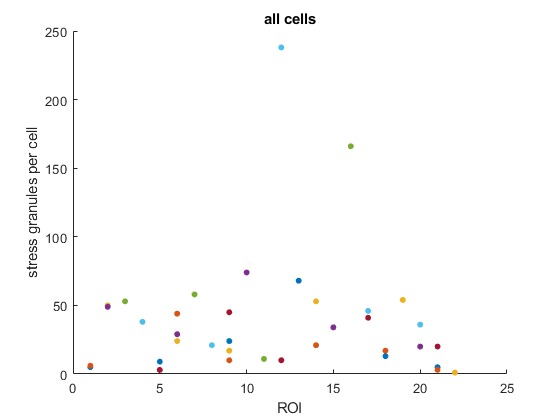


ylabel('stress granules per cell')
xlabel('ROI')
title(sprintf('%s', 'all cells'))
hold off


clear('p', 'm');

% Pull intensities for downstream analysis.

fprintf('%s%s', 'Starting to collect intensities.', newline);

SE = strel('disk', 4);
g = 2;
values = {'SG mean', 'SG median', 'SG max', 'SG stdev', ...
    'bkgd mean', 'bkgd median', 'bkgd stdev', ...
    'ratio of means', 'ratio of medians', 'ratio of max to mean', ...
    'SG size', 'bkgd size'};

figure

for p = 1:size(processed, 1) % for every file
    disp(['Done with ', ND2names{p,1}]);
    probe_img = processed{p,2}; % Probe MIP.
    
    for m = 1:size(processed{p,4}, 1) % for every cell mask in each file
        
        for s = 1:max(max(processed{p,4}{m,3})) % for every SG mask in every cell mask in each file
            [SG_row, SG_col] = find(processed{p,4}{m,3} == s); % get pixel positions of that one SG mask
            SG_mask = false(size(probe_img));
            
            SG_ints = [];
            bkgd_ints = [];
            
            % Reconstitute SG mask for easy dilation and get intensities within SG mask.
            for r = 1:size(SG_row, 1) % for every pixel position in each SG mask ...
                SG_mask(SG_row(r,1), SG_col(r,1)) = true;
                int_i = probe_img(SG_row(r,1), SG_col(r,1)); 
                SG_ints = [SG_ints; int_i];
            end
            
            % Make donut mask for local background. Make one at a time, for SGs that are close to each other.
            SG_larger = imdilate(SG_mask, SE);
            SG_bkgd = SG_larger - SG_mask;
            [bkgd_row, bkgd_col] = find(SG_bkgd == true);
            
            % Get intensities in local background mask.
            for rr = 1:size(bkgd_row, 1) % for every pixel in each local background mask ...
                int_o = probe_img(bkgd_row(rr,1), bkgd_col(rr,1));
                bkgd_ints = [bkgd_ints; int_o];
            end
            
            hold on
            [density, ints] = ksdensity(SG_ints);
            plot(ints, density)
            ylabel('density')
            xlabel('pixel intensity')
            title(sprintf('%s', 'all cells'))
            
%             % Save intensities.
%             processed{p,4}{m,4}{s,1} = SG_ints;
%             processed{p,4}{m,4}{s,2} = bkgd_ints;
            
            % Calculate mean and median intensities and standard deviation.
            % Save.
            values{g,1} = mean(SG_ints, "all"); % SG mean
            values{g,2} = median(SG_ints, "all"); % SG median
            values{g,3} = max(SG_ints); % SG max
            values{g,4} = std(SG_ints, 0, "all"); % SG stdev
            values{g,5} = mean(bkgd_ints, "all"); % bkgd mean
            values{g,6} = median(bkgd_ints, "all"); % bkgd median
            values{g,7} = std(bkgd_ints, 0, "all"); % bkgd stdev
            
            % Calculate ratios. Save.
            values{g,8} = values{g,1} / values{g,5}; % ratio of the means
            values{g,9} = values{g,2} / values{g,6}; % ratio of the medians
            values{g,10} = values{g,3} / values{g,5}; % ratio of max to the mean
            
            values{g,11} = r; % SG size
            values{g,12} = rr; % local background size
            
            g = g + 1;
            
            clear('SG_mask', 'SG_ints', 'bkgd_ints', 'SG_bkgd', 'SG_larger', 'SG_row', 'SG_col', 'bkgd_row', ...
                'bkgd_col', 'int_i', 'int_o', 'r', 'rr');
        end
        disp(['Mask ', ND2names{p,2}{m,1}]);
    end
    clear('probe_img');
end
hold off
num_SGs = g - 1;
clear('p', 'm', 's', 'SE', 'g');

fprintf('%s %d %s%s', 'Values collected for', num_SGs, 'granules.', newline);

% Save values.
filename = input('What would you like to name this file? ', 's');
filename = strcat(filename, '.xlsx');
writecell(values, filename);

separate_cols = true;

% Save intensity values to .xlsx file.
excelname = strsplit(matname, ".mat");
excelname = excelname{1};
excelname = strcat(excelname, '.xlsx');

num_cells = 1;
for p = 1:size(processed,1)
    for m = 1:size(processed{p,3},1)
        for r = 1:size(processed{p,3}{m,2},1)
            cell{r,num_cells} = processed{p,3}{m,2}(r,1);
        end
        num_cells = num_cells + 1;
    end
end

if separate_cols == true
    excel = cell2table(cell);
else
    excel = cat(1, cell{:});
    excel = cell2table(excel);
end

writetable(excel, excelname);

% Plot intensity histograms all together.
figure
for p = 1:size(processed, 1)
    for m = 1:size(processed{p,4},1)
        hold on
        [density, ints] = ksdensity(processed{p,4}{m,2});
        plot(ints, density)
        ylabel('density')
        xlabel('pixel intensity')
        title(sprintf('%s', 'all cells'))
    end
end
hold off

% Plot intensity histograms separately.
for r = 1:size(processed, 1)
    for f = 1:size(processed{r,4}, 1)
        figure
        [density, ints] = ksdensity(processed{r,4}{f,2});
        plot(ints, density)
        ylabel('density')
        xlabel('pixel intensity')
        title(sprintf('%d-%d', r, f))
    end
end
